使用平面波展开法隐式求解空时介质中的场

作者：FTT

创建时间：2024.11.13

clear;
clc;
close all;

定义结构参数

epslion0 = 8.85e-12; % 真空介电常数
mu0 = 4 * pi * 1e-7; % 真空磁导率
epslionr = 1; % 未调制时的相对介电常数
c0 = 3e8; % 光速
d = 60; % 介质长度

调制参数

OMEGA = 2*pi*300e6; % 调制频率
delta = 0; % 速度差
cg = (1 + delta) * c0 / sqrt(epslionr); % 光栅速度
g = OMEGA / cg; % 调制空间频率o
alpha = 0.04; % 调制强度
OmegaInput = 2*pi*10e6; % 入射波频率

精度参数

% 时间因子
tnum = 500;
Omegat = linspace(0, 30 * pi, tnum)'; % 观察2个调制周期
xnum = 500;

采样频率

fks = 1 / (d / xnum);
fws = 1 / (Omegat(end) / OMEGA / tnum);

频谱

length_k = 2 ^ nextpow2(xnum);
length_w = 2 ^ nextpow2(tnum);
fk = (-length_k / 2 : length_k / 2) / (length_k / 2) * fks / 2;
fw = (-length_w / 2 : length_w / 2) / (length_w / 2) * fws / 2;

本征值求解

Omega = OmegaInput; % 扫频范围
OmegaNum = length(Omega); % 扫频点数
Order = 3; % 展开阶数
HarmonicNum = 2 * Order + 1; % 谐波数目（包含正负）
HarmonicSequence = -Order:Order; % 阶次序号

MEE = zeros(HarmonicNum); % 初始化特征矩阵的电场-电场部分
MEH = zeros(HarmonicNum); % 初始化特征矩阵的电场-磁场部分
MHE = zeros(HarmonicNum); % 初始化特征矩阵的磁场-电场部分
MHH = zeros(HarmonicNum); % 初始化特征矩阵的磁场-磁场部分
LuminWaveNumber = zeros(OmegaNum, 2 * HarmonicNum); %初始化相应波数
LuminEigenVec = zeros(2 * HarmonicNum, 2 * HarmonicNum, OmegaNum); % 初始化超材料中特征矩阵，每一页表示一个频点

VacEigenValue = zeros(OmegaNum, 2 * HarmonicNum); % 真空中特征值向量
VacEigenMatrix = zeros(2 * HarmonicNum, 2 * HarmonicNum, OmegaNum); % 初始化真空中特征矩阵
VacEigenH = zeros(OmegaNum, 2 * HarmonicNum); % 初始化真空中特征向量中磁场部分
VacEigenVec = zeros(2 * HarmonicNum, 2 * HarmonicNum, OmegaNum); % 初始化真空中特征向量组矩阵
ForwardVacEigenValue = zeros(OmegaNum, 2 * HarmonicNum); % 真空前向波部分
BackwardVacEigenValue = zeros(OmegaNum, 2 * HarmonicNum); % 真空后向波部分

for loop = 1:OmegaNum
    
    % 处理真空中特征值
    VacEigenValue(loop, 1:HarmonicNum) = -HarmonicSequence * g - sqrt(c0 ^ -2 * (Omega(loop) + HarmonicSequence * OMEGA) .^ 2);
    VacEigenValue(loop, HarmonicNum + 1:2 * HarmonicNum) = -HarmonicSequence * g + sqrt(c0 ^ -2 * (Omega(loop) + HarmonicSequence * OMEGA) .^ 2);
    % 真空特征向量
    VacEigenH(loop, 1:HarmonicNum) = -(HarmonicSequence * g + VacEigenValue(loop, 1:HarmonicNum)) ./ (mu0 * (Omega(loop) + HarmonicSequence * OMEGA));
    VacEigenH(loop, HarmonicNum + 1:2 * HarmonicNum) = -(HarmonicSequence * g + VacEigenValue(loop, HarmonicNum + 1:2 * HarmonicNum)) ./ (mu0 * (Omega(loop) + HarmonicSequence * OMEGA));
    % 分离前向波和后向波部分（取决于k+ng的正负）
    ForwardVacEigenValue(loop, :) = VacEigenValue(loop, :);
    ForwardVacEigenValue(loop, find(VacEigenH(loop, :) >= 0)) = NaN; % 根据E, H, S构成右手系确定前向波
    BackwardVacEigenValue(loop, :) = VacEigenValue(loop, :);
    BackwardVacEigenValue(loop, find(VacEigenH(loop, :) < 0)) = NaN; % 根据E, H, S构成右手系确定后向波
    VacEigenVec11 = diag(ones(HarmonicNum, 1), 0);
    VacEigenVec12 = diag(ones(HarmonicNum, 1), 0);
    VacEigenVec21 = diag(VacEigenH(loop, 1:HarmonicNum), 0);
    VacEigenVec22 = diag(VacEigenH(loop, HarmonicNum + 1:2 * HarmonicNum), 0);
    VacEigenVec(:, :, loop) = [VacEigenVec11, VacEigenVec12; VacEigenVec21, VacEigenVec22];
    % 处理Lumin介质中的特征值
    % 构造Lumin介质的特征矩阵
    for i = 1:HarmonicNum
        for j = 1:HarmonicNum
            if i == j
                MEE(i, j) = - HarmonicSequence(i) * g;
                MEH(i, j) = - mu0 * (Omega(loop) + HarmonicSequence(i) * OMEGA);
                MHE(i, j) = - epslionr * epslion0 * (Omega(loop) + HarmonicSequence(i) * OMEGA);
                MHH(i, j) = - HarmonicSequence(i) * g; 
            elseif i - j == -1 % 主对角线下方
                MHE(i, j) = - epslionr * epslion0 * ((Omega(loop) + HarmonicSequence(i) * OMEGA) * alpha + OMEGA * alpha);
            elseif i - j == 1 % 主对角线上方
                MHE(i, j) = - epslionr * epslion0 * ((Omega(loop) + HarmonicSequence(i) * OMEGA) * alpha - OMEGA * alpha);
            end
        end
    end
    MHE = MHE'; % ??
    LuminEigenMatrix = [MEE, MEH; MHE, MHH]; % 特征矩阵
    [V, D] = eig(LuminEigenMatrix); % 解特征矩阵的特征值和特征向量
    k = diag(D);
    Rek = real(k);
    [Y, I] = sort(Rek);
    k = k(I); % 按顺序重排特征值
    V = V(:, I); % 重排特征向量，每一列对应于一个特征值
    LuminWaveNumber(loop, :) = k;
    LuminEigenVec(:, :, loop) = V;
end

绘制能带图

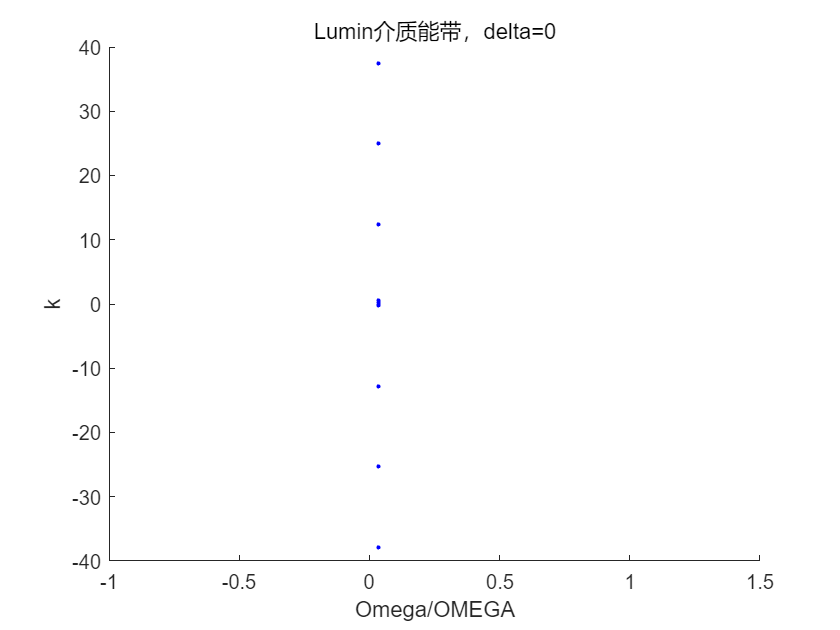

figure('name', '能带');
hold on
% 每一行对应于一个频率，每一列对应于一条线
for band = LuminWaveNumber
    for i = 1:OmegaNum
        if imag(band(i)) == 0
            plot(Omega(i)/OMEGA, real(band(i)), 'b.') % 波数是纯实数，属于通带
        else
            plot(Omega(i)/OMEGA, real(band(i)), 'r.') % 波数不是纯实数，属于禁带
        end
    end
end
xlabel('Omega/OMEGA')
ylabel('k')
title(strcat('Lumin介质能带，delta=', num2str(delta)))

结合边界条件解场

NormOmegaInput = OmegaInput / OMEGA; % 归一化入射角频率
% 找出对应的波数
[~, OmegaInputIndex] = min(abs(Omega/OMEGA-NormOmegaInput)); % 该输入频率对应的索引
OmegaInput = Omega(OmegaInputIndex); % 实际使用入射角频率

% 真空的特征向量矩阵
VacEigenVec = VacEigenVec(:, :, OmegaInputIndex);

% Lumin介质中的特征向量
LuminWaveNumber = LuminWaveNumber(OmegaInputIndex, :);
LuminEigenVec = LuminEigenVec(:, :, OmegaInputIndex);
Mm = LuminEigenVec; % 与论文中符号一致

% 提取真空正向和反向传播的特征向量
Mvinc = VacEigenVec(:, find(VacEigenH(OmegaInputIndex, :) < 0)); % 正向波的特征向量矩阵
Mvref = VacEigenVec(:, find(VacEigenH(OmegaInputIndex, :) > 0)); % 反向波的特征向量矩阵
VIncIndex = find(VacEigenH(OmegaInputIndex, :) < 0); % 正向波原来的索引
HValue = (VacEigenH(OmegaInputIndex, VIncIndex(1)));
[row, col] = find(abs(VacEigenVec - HValue) < 1e-16);
FundamentalIndex = find(VIncIndex == col(find(row == HarmonicNum + (HarmonicNum + 1) / 2))); % 正向基波的在原特征向量矩阵中的索引

% 传输矩阵
P = diag(exp(1i * LuminWaveNumber * d));

% 辅助矩阵
evinc = zeros(size(Mvinc, 2), 1); % 初始化入射相位向量
evinc(FundamentalIndex) = 1; % 基波幅度为1
A = Mm * (Mm * P) ^ -1 * Mvinc;
B = -Mvref;

% 解边界条件方程得相位向量
evtraref = ([A, B]) ^ -1 * (Mvinc * evinc);
evtra = evtraref(1:HarmonicNum);
evref = evtraref(HarmonicNum + 1:2 * HarmonicNum);
em = (Mm ^ -1) * (Mvinc * evinc + Mvref * evref);
x = linspace(0, d, xnum)'; % 距离因子
Px = exp(1i * LuminWaveNumber .* x); % 相移矩阵，每一行代表一个空间点
Em = zeros(xnum, HarmonicNum); % 超材料内电场复矢量，每一行代表一个空间点
Hm = zeros(xnum, HarmonicNum); % 超材料内电场复矢量，每一行代表一个空间点
Elumin = zeros(xnum, tnum);
Hlumin = zeros(xnum, tnum);
eps = epslionr * (1 + 2 * alpha * cos(Omegat))';
for i = 1:xnum
    EHtemp = Mm * diag(Px(i, :)) * em;
    Em(i, :) = EHtemp(1:HarmonicNum);
    Hm(i, :) = EHtemp(HarmonicNum + 1:2 * HarmonicNum);
end

for i = 1:tnum
    Elumin(:, i) = sum(Em .* exp(-1i * ((OmegaInput / OMEGA + HarmonicSequence) * Omegat(i))) .* exp(1i * HarmonicSequence * g .* x), 2); % 超材料内的场
    Hlumin(:, i) = sum(Hm .* exp(-1i * ((OmegaInput / OMEGA + HarmonicSequence) * Omegat(i))) .* exp(1i * HarmonicSequence * g .* x), 2); % 超材料内的场
end

绘制场分布（确定空间）

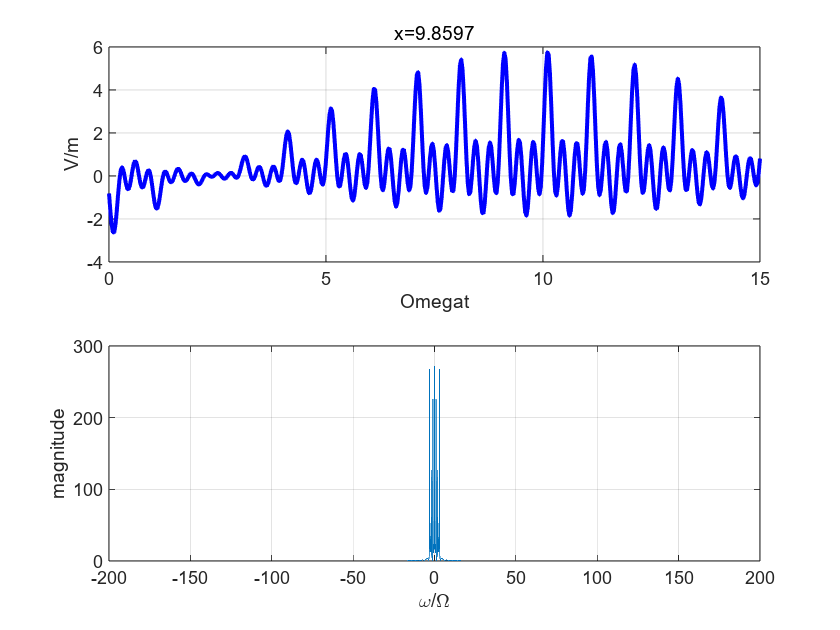

if true
    figure;
    for i = 1:xnum
        subplot(2, 1, 1)
        plot(Omegat/2/pi, real(Elumin(i, :)), 'b', 'LineWidth', 2)
        xlabel('Omegat')
        ylabel('V/m')
        title(strcat('x=', num2str(x(i))))
        grid on
        subplot(2, 1, 2)
        y = fft(real(Elumin(i, :)), 2 ^ nextpow2(tnum) + 1);
        plot(fw * 2 * pi / OMEGA, abs(fftshift(y)))
        xlim([-200 200])
        xlabel('\omega/\Omega')
        ylabel('magnitude')
        grid on
        pause(0.01)
    end
end

绘制场分布（确定时间）

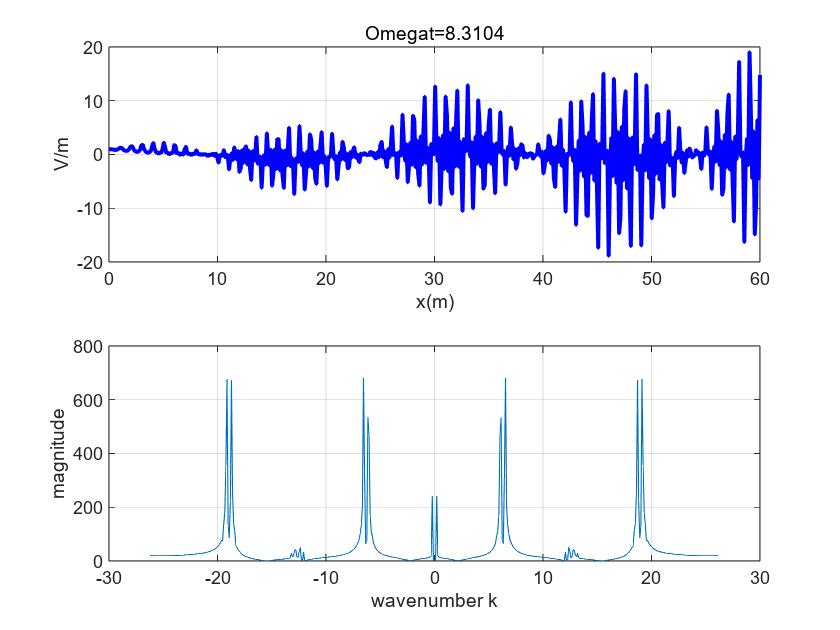

if true
    figure;
    for i = 1:xnum
        subplot(2, 1, 1)
        plot(x, real(Elumin(:, i)), 'b', 'LineWidth', 2)
        xlabel('x(m)')
        ylabel('V/m')
        title(strcat('Omegat=', num2str(Omegat(i))))
        grid on
        subplot(2, 1, 2)
        % 对空间场做傅里叶变换
        y = fft(real(Elumin(:, i)), 2 ^ nextpow2(xnum) + 1);
        plot(fk * 2 * pi, abs(fftshift(y)))
        % xlim([-200 200])
        xlabel('wavenumber k')
        ylabel('magnitude')
        grid on
        pause(0.01)
    end
end

放大倍数曲线

PA = max(abs(Elumin).^2, [], 2);
figure;
plot(x/cg*OMEGA/2/pi, PA)
title('放大倍数曲线')
xlim([0 7.5])
grid on

figure;
imagesc(x, Omegat / 2 / pi, real(Elumin'))
colormap('jet')
colorbar
xlabel('x/m')
ylabel('\Omegat')
title('时空图')

用计算出来的场再通过傅里叶变换得到能带

Ekw = fft2(real(Elumin'), 2 ^ nextpow2(xnum) + 1, 2 ^ nextpow2(tnum) + 1);
NormEkw = abs(fftshift(Ekw)) / max(abs(fftshift(Ekw)), [], 'all');

figure;
imagesc(fk * 2 * pi / g, fw * 2 * pi / OMEGA, NormEkw)
colormap('jet')
colorbar
xlabel('k/g')
ylabel('\omega/\Omega')